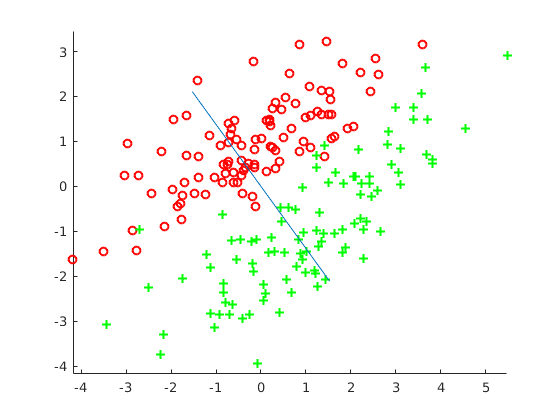

% Task 3
load ./Ex_12/testdata_fisher.mat
scatter(X1(:,1), X1(:,2), 'red','o', 'LineWidth',1.5);
hold on
scatter(X2(:,1), X2(:,2), 'green','+', 'LineWidth',1.5);
u1 = (mean(X1,1))';
u2 = (mean(X2,1))';
c1 = cov(X1);
c2 = cov(X2);
w = (inv(c1 + c2))*(u1-u2);
hold on
line([-w(1) w(1)],[-w(2),w(2)])
axis equal;
hold off

% Task 4
u1_projection = dot(w,u1);
u2_projection = dot(w, u2);
c = (u1_projection+u2_projection)/2

c = -0.6592


count1=0;
count2=0;
for i=1:length(X1)
    if (dot(X1(i,:),w)>=c)
        count1=count1+1;
    end
    if (dot(X2(i,:),w)<c)
        count2=count2+1;
    end
end

precentage=((count1+count2)/(length(X1)+length(X2)))*100;
disp(["Percentage of the samples that are classified correctly: ", precentage])

    "Percentage of the samples that are classified correctly: "    "96.5"



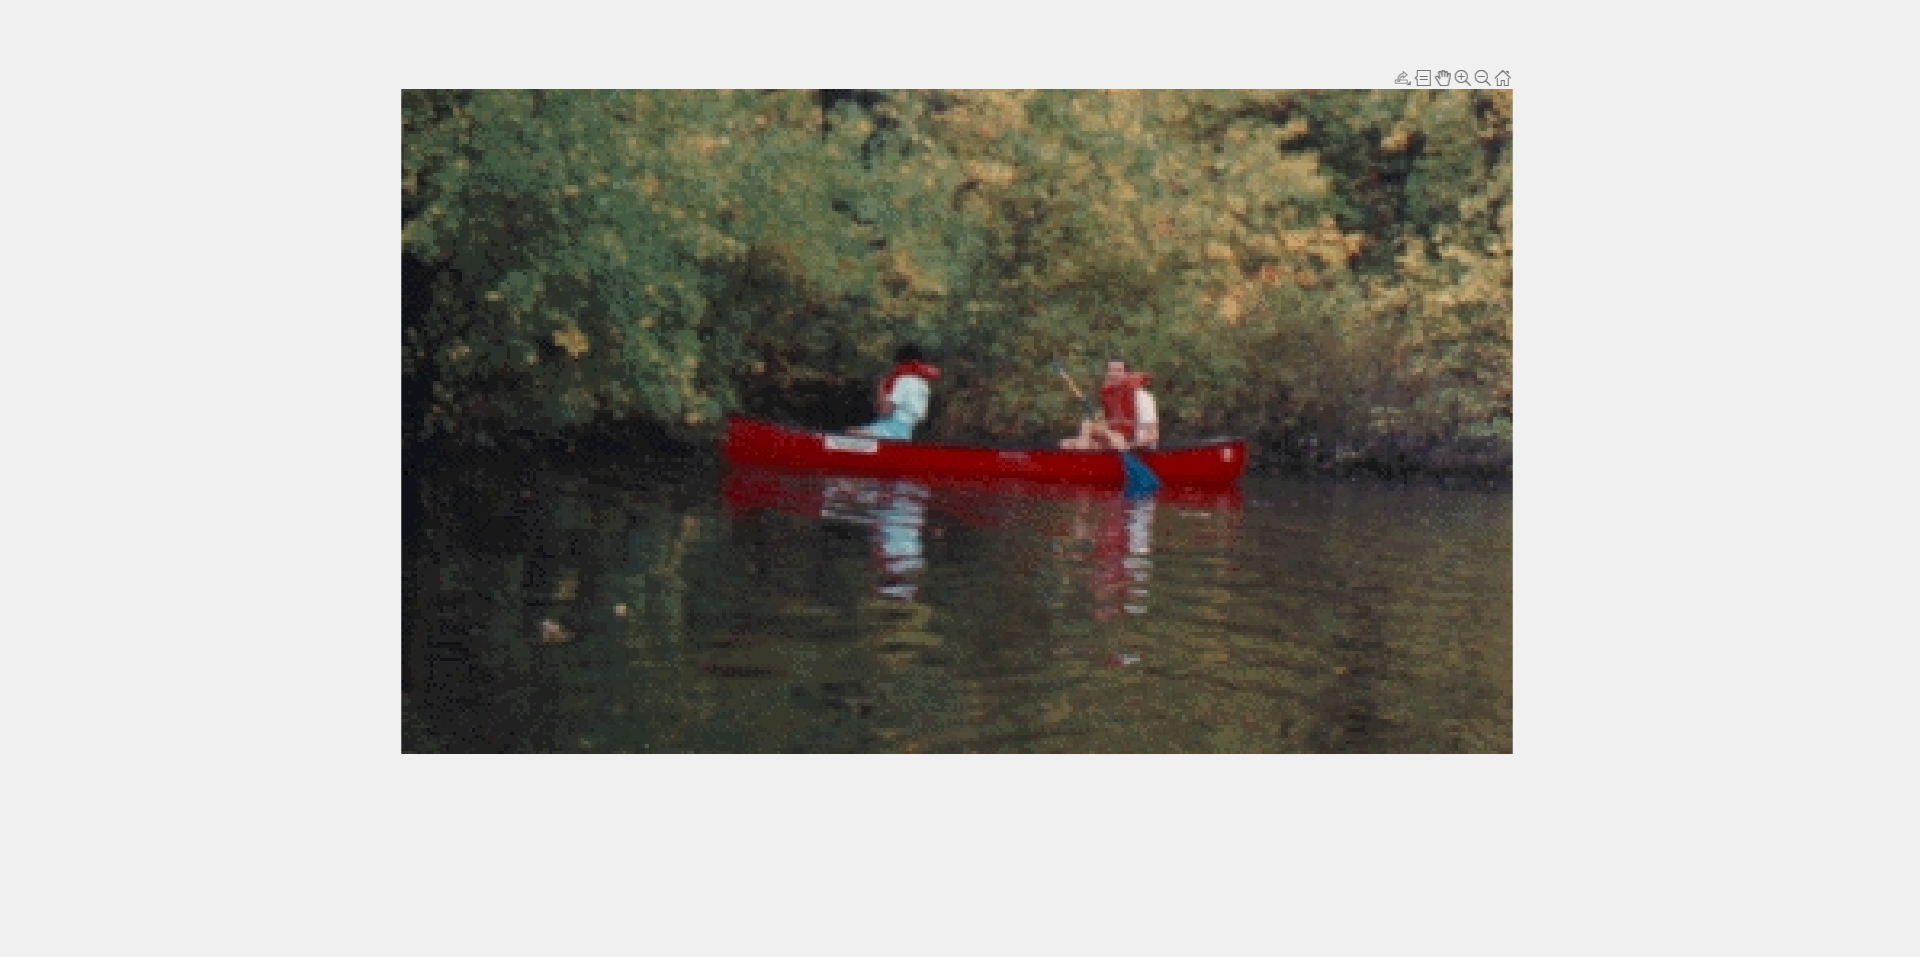

% Task 5
imOrig = imread('./Ex_12/canoe.jpg');
imshow (imOrig, []);

[x1,y1] = ginput(1);
[x2,y2] = ginput(1);


window1 = imOrig(y1-3:y1+3, x1-3:x1+3,:);

window2 = imOrig(y2-3:y2+3, x2-3:x2+3,:);

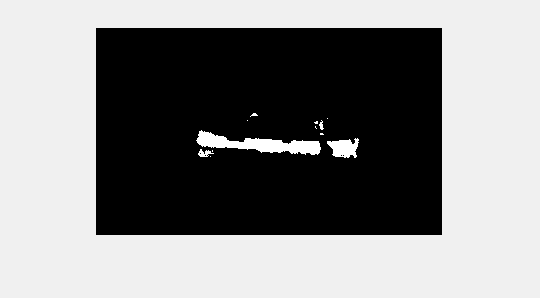


X1 = double(reshape(window1, 49, 3))';
X2 = double(reshape(window2, 49, 3))';

u1 = mean(X1,2);
u2 = mean(X2,2);
c1 = cov(X1');
c2 = cov(X2');
w = (inv(c1 + c2))*(u1-u2);

u1_projection=dot(w,u1);
u2_projection=dot(w,u2);

threshold=(u1_projection+u2_projection)/2;

imGray = w(1)*double(imOrig(:,:,1)) +...
w(2)*double(imOrig(:,:,2)) +...
w(3)*double(imOrig(:,:,3));

imshow(imGray > threshold, []);